# Problema 10


$$f\left(x\right)=\frac{e^x -1-x}{x^2 }$$


Daca x ~= 0, f(x)  are o eroare numerica mare, numit si catastrophic cancellation. $e^x \;$la valori foarte mici ajunge sa fie 1+x care ar fi aproximativ 0, impartind la $x^2$poate amplifica erorile.

Ca si solutie am dezolvat $e^x$ cu seria s a Taylor si am ajuns ca f(x) sa arate astfel:


$$f\left(x\right)=\frac{1}{2}+\frac{x}{6}+\frac{x^2 }{24}+O\left(x^3 \right)$$


function f = stable_f(x)
    % Pragul sub care folosim seria Taylor
    threshold = 1e-4;
    
    % Initializam vectorul rezultat f cu aceeași dimensiune ca x
    f = zeros(size(x));
    
    small_x = abs(x) < threshold;
    
    % f(x) ≈ 1/2 + x/6 + x^2/24
    x_small = x(small_x);
    f(small_x) = (1/2) + (x_small / 6) + (x_small.^2 / 24);
    
    % Gasim valorile mari de x 
    large_x = ~small_x;
    
    % f(x) = (e^x - 1 - x) / x^2
    x_large = x(large_x);
    exp_x = exp(x_large);       % Calculam e^x
    numerator = exp_x - 1 - x_large; % e^x - 1 - x
    denominator = x_large.^2;        % x^2
    f(large_x) = numerator ./ denominator;
end


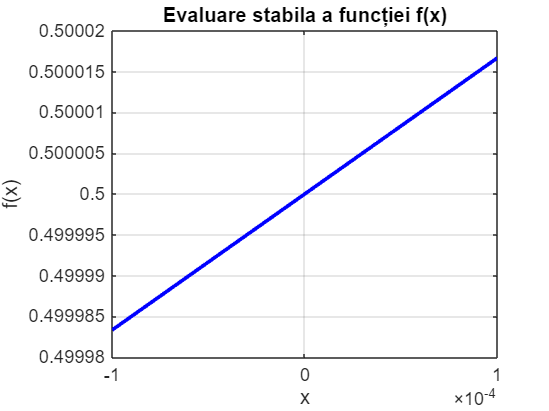

clc; clear; close all;

% Am luat 10 valori intre -0.001 si 0.001
x = linspace(-0.0001, 0.0001, 100);

% Calculam f(x) folosind metoda stabila
f_values = stable_f(x);

% Plotam funcția
figure;
plot(x, f_values, 'b', 'LineWidth', 2);
xlabel('x');
ylabel('f(x)');
title('Evaluare stabila a funcției f(x)');
grid on;